# 4.4. Транизстор как усилитель

#### Усилитель с общим эмиттером с эмиттерным сопротивлением

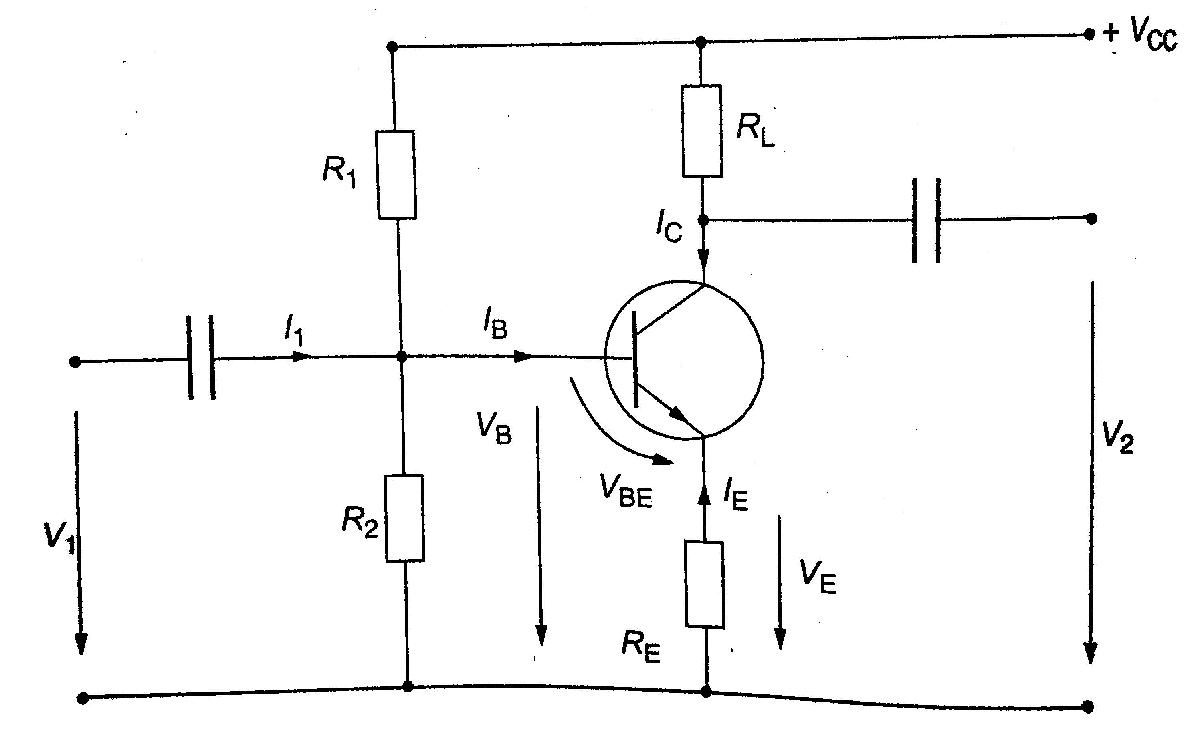

*Рабочая точка (точка устойчивой работы. Q точка)*

clear
syms V_B V_CC R1 R2 I_B
V_B==R2*(V_CC-R1*I_B)/(R1+R2)

$$ans = V_{B}=\frac{R_{2}\,\left(V_{\mathrm{CC}}-I_{B}\,R_{1}\right)}{R_{1}+R_{2}}$$

*Коэффициенты устойчивости*

syms S0 I_C(I_CO) h_FE R_P R_E 
S0==diff(I_C,I_CO)==(1+h_FE)*(1+R_P/R_E)/(1+h_FE+R_P/R_E) % ~1+R_P/R_E

$$ans(I\_CO) = \left(S_{0}=\frac{\partial }{\partial I_{\mathrm{CO}}}I_{C}\left(I_{\mathrm{CO}}\right)\right)=\frac{\left(\frac{R_{P}}{R_{E}}+1\right)\,\left(h_{\mathrm{FE}}+1\right)}{h_{\mathrm{FE}}+\frac{R_{P}}{R_{E}}+1}$$

R_P==R1*R2/(R1+R2)

$$ans = R_{P}=\frac{R_{1}\,R_{2}}{R_{1}+R_{2}}$$

syms S1 S2 I_C V_BE
S1==I_C/V_BE==-h_FE/(R_P+(1+h_FE)*R_E) %~-1/R_E

$$ans = \left(S_{1}=\frac{I_{C}}{V_{\mathrm{BE}}}\right)=-\frac{h_{\mathrm{FE}}}{R_{P}+R_{E}\,\left(h_{\mathrm{FE}}+1\right)}$$

S2==I_C/h_FE==I_C*S0/(h_FE*(1+h_FE))

$$ans = \left(S_{2}=\frac{I_{C}}{h_{\mathrm{FE}}}\right)=\frac{I_{C}\,S_{0}}{h_{\mathrm{FE}}\,\left(h_{\mathrm{FE}}+1\right)}$$

syms DI_C Dh_FE I_C1 I_C2 h_FE1 h_FE2 S02
DI_C/Dh_FE==(I_C2-I_C1)/(h_FE2-h_FE1)==I_C1*S02/(h_FE1*(1+h_FE2))

$$ans = \left(\frac{{\mathrm{DI}}_{C}}{{\mathrm{Dh}}_{\mathrm{FE}}}=\frac{I_{\mathrm{C1}}-I_{\mathrm{C2}}}{h_{\mathrm{FE1}}-h_{\mathrm{FE2}}}\right)=\frac{I_{\mathrm{C1}}\,S_{02}}{h_{\mathrm{FE1}}\,\left(h_{\mathrm{FE2}}+1\right)}$$

% S02=S0 если I_C=I_C2 и h_FE=h_FE2
% I_CO = обратный ток коллектор-база
syms DI_C DI_CO S1 DV_BE S2 Dh_BE
DI_C==S0*DI_CO+S1*DV_BE+S2*Dh_FE

$$ans = {\mathrm{DI}}_{C}={\mathrm{DI}}_{\mathrm{CO}}\,S_{0}+{\mathrm{DV}}_{\mathrm{BE}}\,S_{1}+{\mathrm{Dh}}_{\mathrm{FE}}\,S_{2}$$

*Примерный низкочастотный коэффициент усиления по току и напряжению каскада с общим эмиттером (см.также раздел 4.2)*

syms A_i i_C i1 h_fe R_P R_B
A_i==-i_C/i1==-h_fe*R_P/(R_B+R_P)

$$ans = \left(A_{i}=-\frac{i_{C}}{i_{1}}\right)=-\frac{R_{P}\,h_{\mathrm{fe}}}{R_{B}+R_{P}}$$

R_B==h_fe+(1+h_fe)*R_E

$$ans = R_{B}=h_{\mathrm{fe}}+R_{E}\,\left(h_{\mathrm{fe}}+1\right)$$

syms A_v v1 v2 R_L R_in
A_v==v2/v1==A_i*R_L/R_in

$$ans = \left(A_{v}=\frac{v_{2}}{v_{1}}\right)=\frac{A_{i}\,R_{L}}{R_{\mathrm{in}}}$$

Входное сопротивление

syms R_p R_B
R_in==v1/i1==R_p*R_B/(R_p+R_B)

$$ans = \left(R_{\mathrm{in}}=\frac{v_{1}}{i_{1}}\right)=\frac{R_{B}\,R_{p}}{R_{B}+R_{p}}$$

*Примерный коэффициент усиления по току и напряжению эмиттерного повторителя*

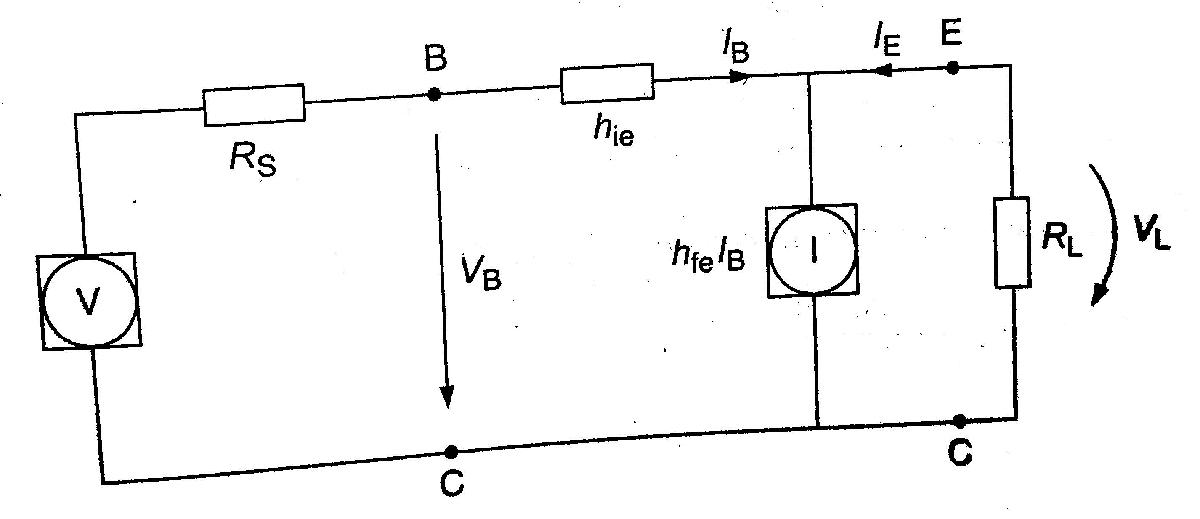

syms i_E i_B v_L v_B Z_i h_ie
A_i==-i_E/i_B==1+h_fe

$$ans = \left(A_{i}=-\frac{i_{E}}{i_{B}}\right)=h_{\mathrm{fe}}+1$$

A_v==v_L/v_B==(1+h_fe)*R_L/Z_i

$$ans = \left(A_{v}=\frac{v_{L}}{v_{B}}\right)=\frac{R_{L}\,\left(h_{\mathrm{fe}}+1\right)}{Z_{i}}$$

% если
Z_i==v_B/i_B==h_ie+R_L*(1+h_fe)

$$ans = \left(Z_{i}=\frac{v_{B}}{i_{B}}\right)=h_{\mathrm{ie}}+R_{L}\,\left(h_{\mathrm{fe}}+1\right)$$

*Полевой транзистор как усилитель*

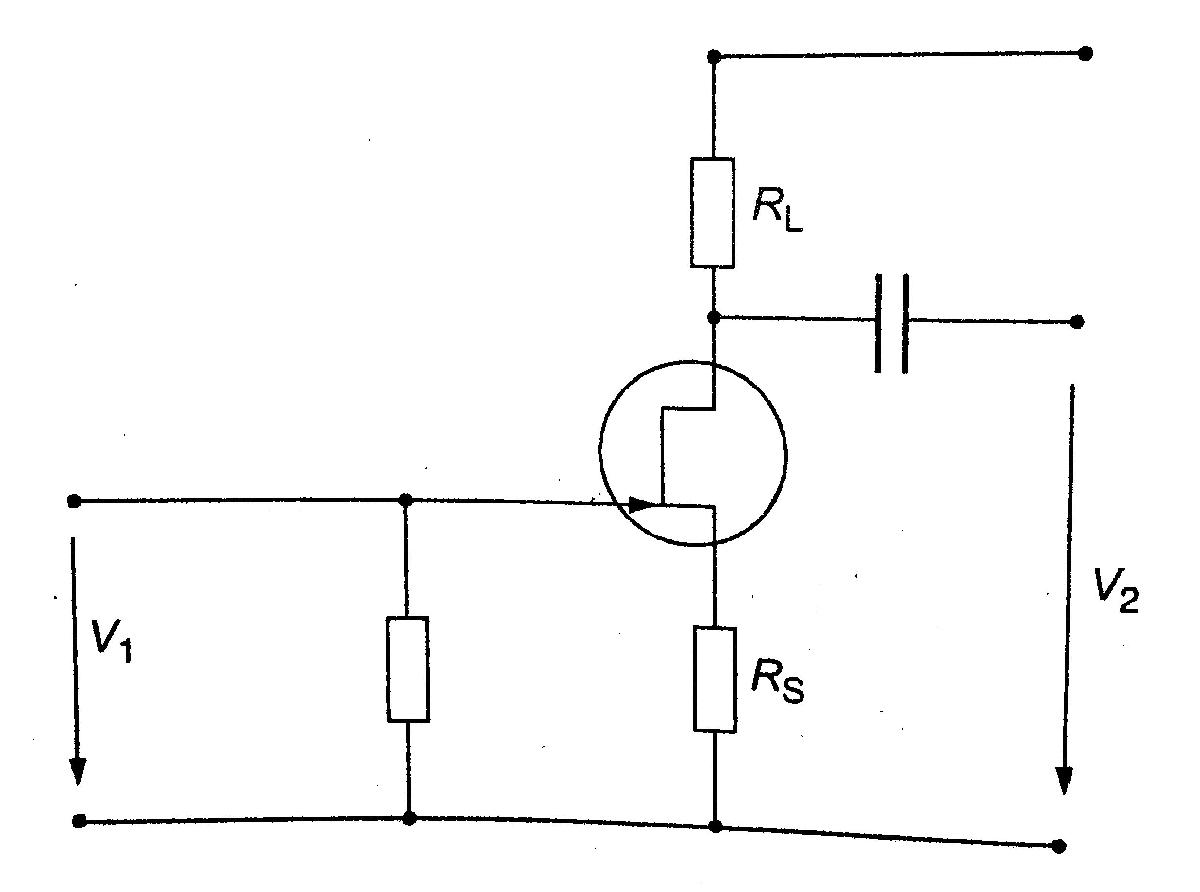

syms A_v v1 v2 g_m R_L R_S r_d
A_v==v2/v1==g_m*R_L/(1+g_m*R_S+(R_S+R_L)/r_d)

$$ans = \left(A_{v}=\frac{v_{2}}{v_{1}}\right)=\frac{R_{L}\,g_{m}}{R_{S}\,g_{m}+\frac{R_{L}+R_{S}}{r_{d}}+1}$$

% g_m = крутизна транзистора
% r_d = сопротивление стока транзистора

*Эквивалентная схема каскада с общим эмиттером и гибридные pi-параметры для высоких частот*

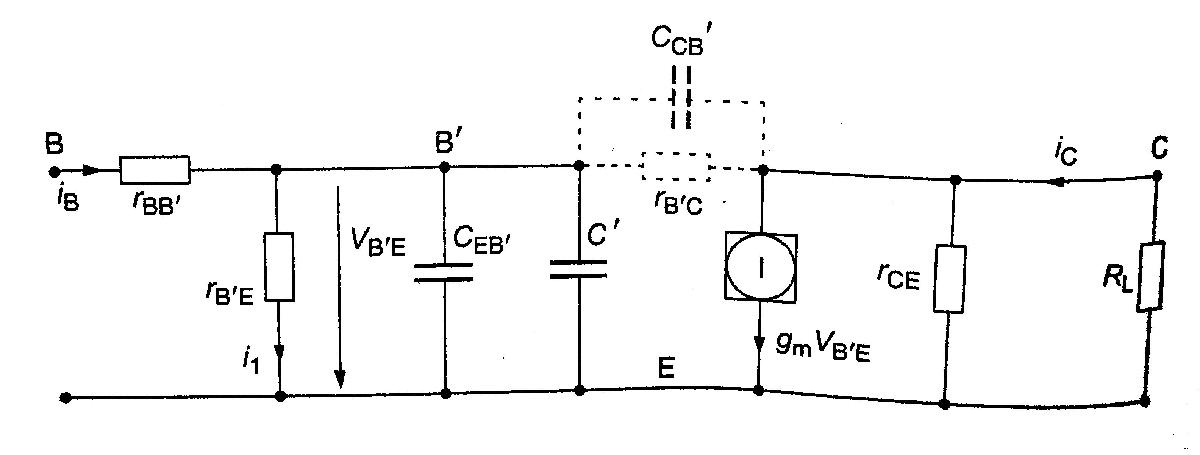

syms C1 C_CB1 g_m R_L r_CE 
C1==C_CB1*(1+g_m*R_L*r_CE/(R_L+r_CE))

$$ans = C_{1}=C_{\mathrm{CB1}}\,\left(\frac{R_{L}\,g_{m}\,r_{\mathrm{CE}}}{R_{L}+r_{\mathrm{CE}}}+1\right)$$

% C_CB1 = емкость коллектор-база
syms eta V_T
g_m=abs(I_C)/(eta*V_T)

$$g\_m = \frac{\left|I_{C}\right|}{V_{T}\,\eta }$$

% eta = фактор идеальности
% eta_He = 1 
% eta_Si = 2
syms k T e
V_T==k*T/e % = 26 мВ при комнатной температуре

$$ans = V_{T}=\frac{T\,k}{e}$$

Предельная частота усиления по току (предел 3 дБ)

syms f_beta r_B1E C_EB1 C1
f_beta==1/(2*pi*r_B1E*(C_EB1+C1))

$$ans = f_{\beta }=\frac{1}{2\,r_{\mathrm{B1E}}\,\pi \,\left(C_{1}+C_{\mathrm{EB1}}\right)}$$

Коэффициент усиления по току с короткозамкнутым выходом

syms beta h_fe i_C i1 beta0 f f_beta f_T
beta==h_fe==i_C/i1==beta0/(1+j*f/f_beta)

$$ans = \left(\left(\beta =h_{\mathrm{fe}}\right)=\frac{i_{C}}{i_{1}}\right)=\frac{\beta_{0}}{1+\frac{f\,\mathrm{i}}{f_{\beta }}}$$

beta0==f_beta*beta0

$$ans = \beta_{0}=\beta_{0}\,f_{\beta }$$

Произведение усиление-полоса (частота перехода)

f_T==f*beta % если f>f_beta

$$ans = f_{T}=\beta \,f$$

% f_T = частота для beta=1, выход закорочен

*Связи между гибридными параметрами*

syms h_ie r_BB1 r_B1E r_CE h_oe h_fe r_B1C R_B1E
h_ie==r_BB1+r_B1E

$$ans = h_{\mathrm{ie}}=r_{\mathrm{BB1}}+r_{\mathrm{B1E}}$$

1/r_CE==h_oe-(1+h_fe)/r_B1C

$$ans = \frac{1}{r_{\mathrm{CE}}}=h_{\mathrm{oe}}-\frac{h_{\mathrm{fe}}+1}{r_{\mathrm{B1C}}}$$

h_ie==R_B1E/(r_B1E+r_B1C)==r_B1E/r_B1C

$$ans = \left(h_{\mathrm{ie}}=\frac{R_{\mathrm{B1E}}}{r_{\mathrm{B1C}}+r_{\mathrm{B1E}}}\right)=\frac{r_{\mathrm{B1E}}}{r_{\mathrm{B1C}}}$$

% h_ie h_re h_fe h_oe определены в разделе 4.2